# **Runge Kutta 4 RLC**

Diego Alejandro Espejo López A01638341

Daniel Esparza Arizpe A01637076

Diego Alberto Cisneros Fajardo A01643454

Daniel Estrada Ocaña A01369854


$$\begin{array}{l}
\frac{\textrm{dy}}{\textrm{dt}}=z\\
\frac{\textrm{dz}}{\textrm{dt}}=-\frac{R}{L}z-\frac{1}{\textrm{LC}}y+\frac{1}{L}E\left(t\right)
\end{array}$$


y $\longrightarrow$ Corriente del circuito

z $\longrightarrow$ Carga del circuito

Crea una función en Matlab para simular el comportamiento de la ***Carga*** y la ***Corriente*** en un circuito **RLC** para diferentes valores de **R**,**L**,**C** y **E(t) **proporcionados por el usuario.�

Comprueba tu función con un escenario durante **8 segundos** con un tamaño de paso **0.2 seg.** con los valores iniciales siguientes para el circuito, suponiendo un circuito inicial descargado:

- **R = 6 [Ohms]**

- **L = 0.5  [Henries]**

- **C = 0.2  [Faradios]**

- **Et = 24  [Volts (constante)]**


$$\frac{\textrm{dy}}{\textrm{dt}}=z$$


$\frac{\textrm{dz}}{\textrm{dt}}=-12z-\frac{1}{0\ldotp 1}y+48$�

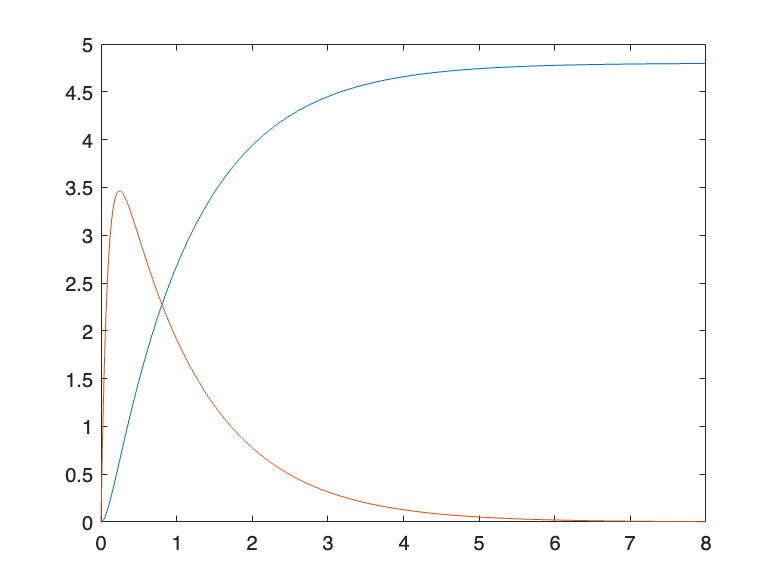

clear; clc;

% Variables
ti = 0;
yi = 0;
zi = 0;
h = 0.02; % Uso 0.02 en lugar de 0.2 para que la gráfica sea exacta
tf = 8;
f1 = "z";
f2 = "-12*z - (1/0.1)*y + 48";

[t,y,z] = runge_kutta_RLC(ti,yi,zi,h,tf,f1,f2);

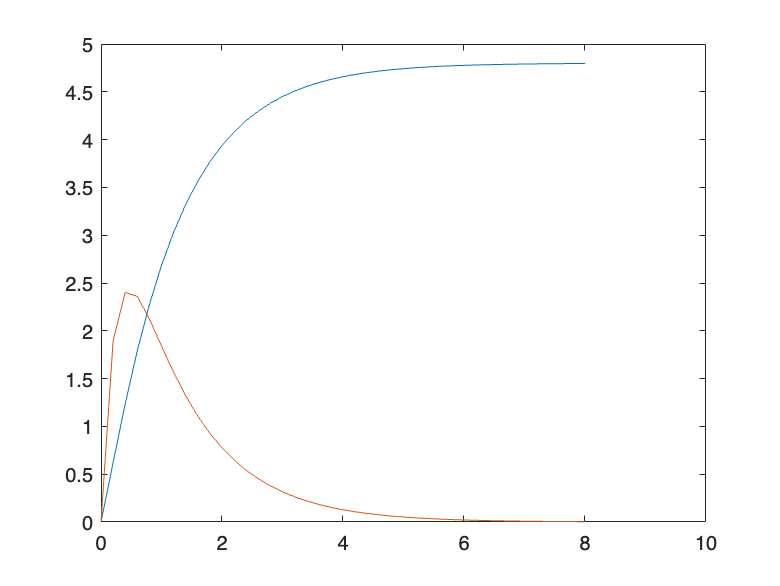

[t,y,z] = runge_kutta_RLC(ti,yi,zi,0.2,tf,f1,f2); % Con 0.2 segundos como pide la actividad

function [t,y,z] = runge_kutta_RLC(ti, yi, zi, h, tf, f1, f2)
    n = (tf - ti) / h;
    
    % Hacemos los vectores
    t = zeros(1, n+1);
    y = zeros(1, n+1);
    z = zeros(1, n+1);
    t(1) = ti;
    y(1) = yi; 
    z(1) = zi;
    
    % Funciones
    f1 = str2func(strcat("@(t,y,z)", f1));
    f2 = str2func(strcat("@(t,y,z)", f2));
    
    for i=1:n
        t(i+1) = t(i) + h;
    
        % K1
        k11 = f1(t(i), y(i), z(i));
        k12 = f2(t(i), y(i), z(i));
    
        % K2
        k21 = f1(t(i) + h/2, y(i) + (h/2)*k11, z(i) + (h/2)*k12);
        k22 = f2(t(i) + h/2, y(i) + (h/2)*k11, z(i) + (h/2)*k12);
    
        % K3
        k31 = f1(t(i) + h/2, y(i) + k21*(h/2), z(i) + k22*(h/2));
        k32 = f2(t(i) + h/2, y(i) + k21*(h/2), z(i) + k22*(h/2));
    
        % K4
        k41 = f1(t(i) + h, y(i) + h*k31, z(i) + h*k32);
        k42 = f2(t(i) + h, y(i) + h*k31, z(i) + h*k32);
    
        y(i+1) = y(i) + (h/6)*(k11 + 2*k21 + 2*k31 + k41);
        z(i+1) = z(i) + (h/6)*(k12 + 2*k22 + 2*k32 + k42);
    end
    plot(t,y,t,z)
end